# Laboratorio 1 - Análisis de las características de un Robot Industrial y Modelo geométrico directo

#### Grupo 8

Ardila, Juan Andrés

López, Nicolás

Rojas, Juan Camilo

## Parte 1 - Robot

### Asignación del robot

Para el grupo 8, el robot asignado es el Fanuc R-2000iC/125L

### Características y modelo del robot

1.

a) Imágen del robot

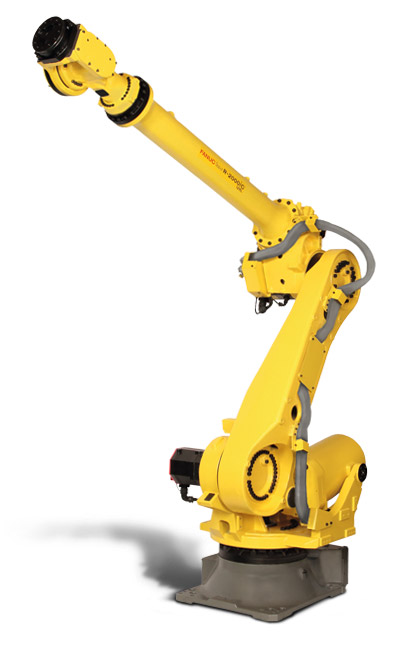

b) Capacidad de carga

125 kg

c) Alcance vertical y horizontal

3100 mm horizontal y 3490 mm vertical

d) Repetitibilidad

$\pm 0.05$mm basado en ISO9283

e) Gráfica(s) de espacio alcanzable

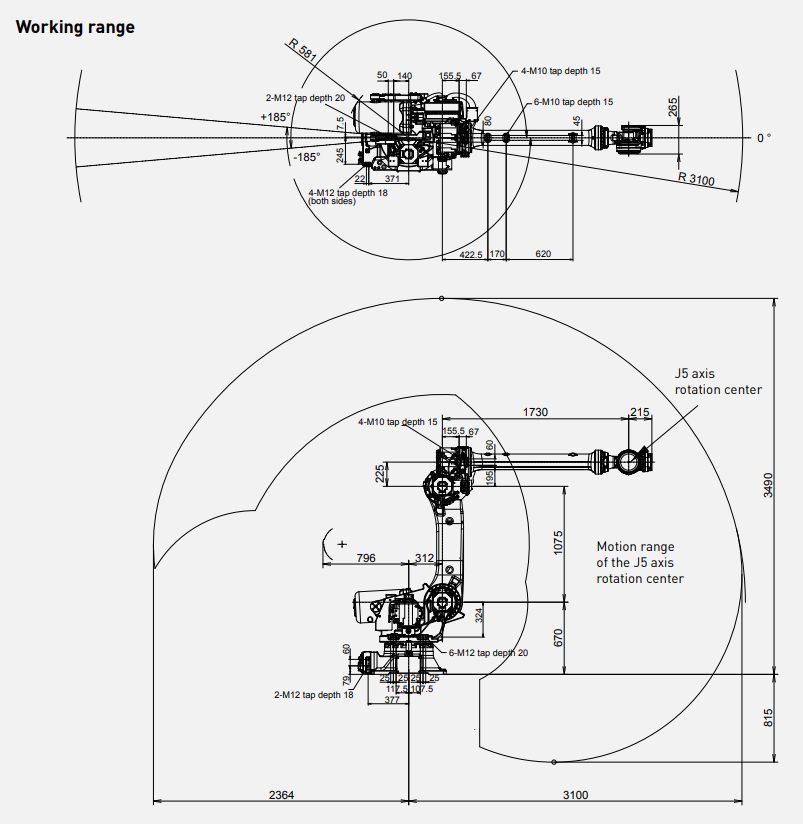

f) Tabla de parámetros DH

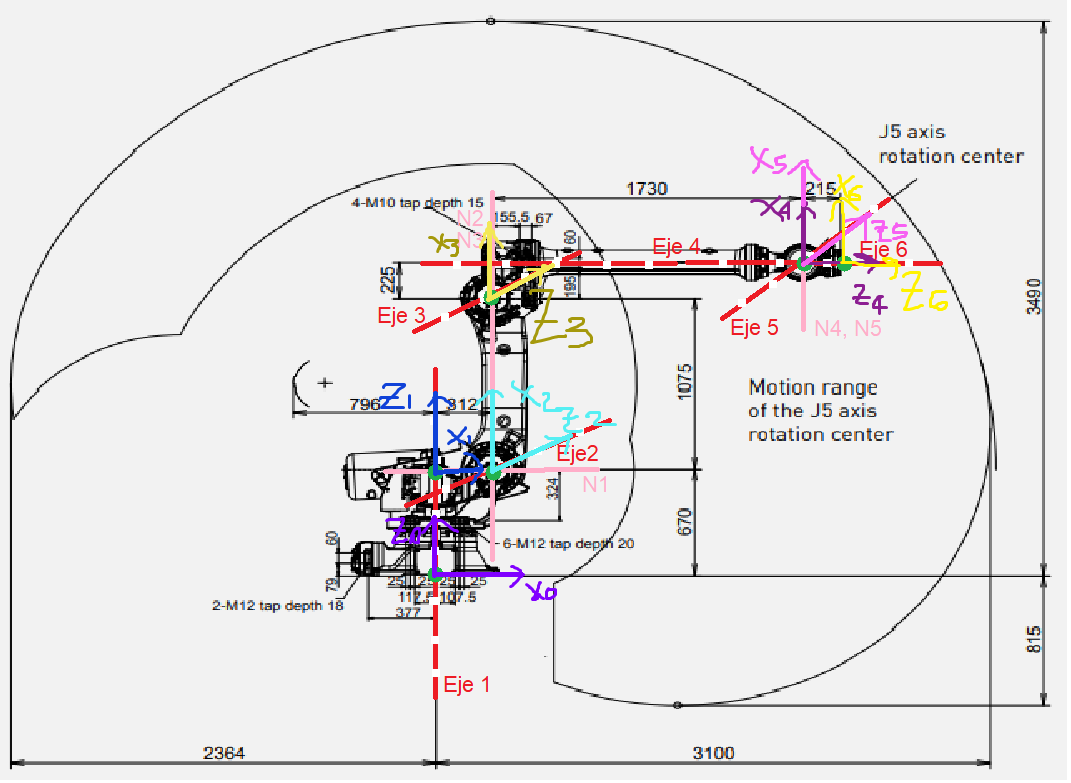

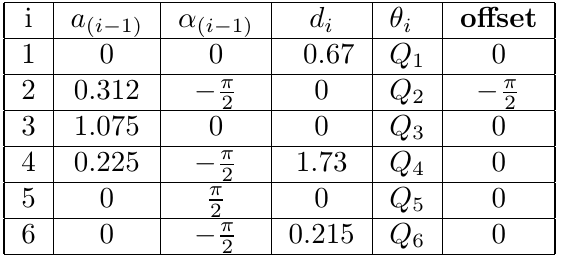

g) Qué software utiliza el fabricante para diseño de celdas o programación

Este modelo de robot está integrado en el software de programación offline de FANUC, ROBOGUIDE. ROBOGUIDE es una potente herramienta que permite a los integradores, planificadores y usuarios diseñar células, sistemas y simular movimientos offline.

h) ¿Qué otras características tiene? (Grado de protección IP, colaborativo, normas de seguridad etc.) 

Conexión eléctrica

Voltaje 50/60Hz trifásico 380-575 V

Consumo promedio de energía 2.5 kW

Suministro de aire integrado: 2

Nivel de ruido acústico 70.5 dB

Temperatura ambiente: 0-45 °C

Protección de cuerpo (estándar/opcional): IP54/IP56

Protección de muñeca brazo J3 (estándar/opcional): IP67 

i) Haga un análisis del diagrama de la capacidad de carga.

No hay diagrama de la capacidad de carga del robot, lo único que se tiene es el dato de la capacidad máxima. A partir de esta se puede saber para qué aplicaciones sirve, en este caso nos dice que puede ser para procesos de soldadura de alta velocidad, montaje, transferencia de piezas, eliminación de material, carga y dispensación, entre otros.

2. Según las características anteriores explique para qué aplicaciones se usa este robot.

Es el robot adecuado para aplicaciones de carga pesada que requieran una repetibilidad excelente. Es el especialista en soldadura por puntos, gracias a su alto rendimiento, fácil instalación, diseño estilizado y gran cantidad de funciones adicionales, es la solución definitiva de soldadura. Como tiene elevada repetibilidad y una considerable carga de trabajo para aplicaciones de ensamble, transferencia de piezas, eliminación de material, servicio integrado  dispensado.

## Parte 2 - Modelos

### Iniciando

- Realice el análisis geométrico del robot asignado a través de DH modificado y utilice las funciones de RVC para construir un modelo en alambres.

clear
L(1) = Link('revolute','alpha',0,    'a', 0,    'd',0.67, 'offset',0,  ...
    'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha',-pi/2,'a', 0.312,'d',0,    'offset',-pi/2,...
    'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha',0,    'a', 1.075,'d',0,    'offset',0,  ...
    'modified', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha',-pi/2,'a', 0.225,'d',1.73, 'offset',0, ...
    'modified', 'qlim',[0 5]);
L(5) = Link('revolute','alpha',pi/2,  'a', 0,   'd',0,    'offset',0, ...
    'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha',-pi/2, 'a', 0,   'd',0.215,'offset',0, ...
    'modified', 'qlim',[-pi pi]);

syms Q1 Q2 Q3 Q4 Q5 Q6 real
A_0_1 = L(1).A(Q1)

$$A\_0\_1 = \left(\begin{array}{cccc} \cos\left(Q_{1}\right) & -\sin\left(Q_{1}\right) & 0 & 0\\ \sin\left(Q_{1}\right) & \cos\left(Q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & \frac{67}{100}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_1_2 = L(2).A(Q2)

$$A\_1\_2 = \left(\begin{array}{cccc} \cos\left(Q_{2}-\frac{\pi }{2}\right) & -\sin\left(Q_{2}-\frac{\pi }{2}\right) & 0 & \frac{39}{125}\\ \frac{4967757600021511\,\sin\left(Q_{2}-\frac{\pi }{2}\right)}{81129638414606681695789005144064} & \frac{4967757600021511\,\cos\left(Q_{2}-\frac{\pi }{2}\right)}{81129638414606681695789005144064} & 1 & 0\\ -\sin\left(Q_{2}-\frac{\pi }{2}\right) & -\cos\left(Q_{2}-\frac{\pi }{2}\right) & \frac{4967757600021511}{81129638414606681695789005144064} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_2_3 = L(3).A(Q3)

$$A\_2\_3 = \left(\begin{array}{cccc} \cos\left(Q_{3}\right) & -\sin\left(Q_{3}\right) & 0 & \frac{43}{40}\\ \sin\left(Q_{3}\right) & \cos\left(Q_{3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_3_4 = L(4).A(Q4)

$$A\_3\_4 = \left(\begin{array}{cccc} \cos\left(Q_{4}\right) & -\sin\left(Q_{4}\right) & 0 & \frac{9}{40}\\ \frac{4967757600021511\,\sin\left(Q_{4}\right)}{81129638414606681695789005144064} & \frac{4967757600021511\,\cos\left(Q_{4}\right)}{81129638414606681695789005144064} & 1 & \frac{173}{100}\\ -\sin\left(Q_{4}\right) & -\cos\left(Q_{4}\right) & \frac{4967757600021511}{81129638414606681695789005144064} & \frac{4297110324018607}{40564819207303340847894502572032}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_4_5 = L(5).A(Q5)

$$A\_4\_5 = \left(\begin{array}{cccc} \cos\left(Q_{5}\right) & -\sin\left(Q_{5}\right) & 0 & 0\\ \frac{4967757600021511\,\sin\left(Q_{5}\right)}{81129638414606681695789005144064} & \frac{4967757600021511\,\cos\left(Q_{5}\right)}{81129638414606681695789005144064} & -1 & 0\\ \sin\left(Q_{5}\right) & \cos\left(Q_{5}\right) & \frac{4967757600021511}{81129638414606681695789005144064} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_5_6 = L(6).A(Q6)

$$A\_5\_6 = \left(\begin{array}{cccc} \cos\left(Q_{6}\right) & -\sin\left(Q_{6}\right) & 0 & 0\\ \frac{4967757600021511\,\sin\left(Q_{6}\right)}{81129638414606681695789005144064} & \frac{4967757600021511\,\cos\left(Q_{6}\right)}{81129638414606681695789005144064} & 1 & \frac{43}{200}\\ -\sin\left(Q_{6}\right) & -\cos\left(Q_{6}\right) & \frac{4967757600021511}{81129638414606681695789005144064} & \frac{8544543072036999}{649037107316853453566312041152512}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Modelo geométrico directo:

T_0_6 = A_0_1 * A_1_2 * A_2_3 * A_3_4 * A_4_5 * A_5_6 *eye(4);
T_0_6 = simplify(T_0_6)


q0 = [0 0 0 0 0 0]

q0 =      0     0     0     0     0     0


ws = [-5 6 -5 6 -2 5];
plot_options = {'workspace',ws,'scale',.5,'view',[-5 25], 'tilesize',2, ...
    'ortho', 'lightpos',[2 2 10] };

figure(1)
Robot = SerialLink(L,'name','R_{Fanuc}', 'plotopt', plot_options)

 
Robot = 
 
R_{Fanuc} (6 axis, RRRRRR, modDH, fastRNE)                       
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|       0.67|          0|          0|          0|
|  2|         q2|          0|      0.312|     -1.571|     -1.571|
|  3|         q3|          0|      1.075|          0|          0|
|  4|         q4|       1.73|      0.225|     -1.571|          0|
|  5|         q5|          0|          0|      1.571|          0|
|  6|         q6|      0.215|          0|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0            

Robot.teach(q0)

it = 8;

q1 = linspace(-180,180,it)*pi/180;
q2 = linspace(-180,180,it)*pi/180;
q3 = linspace(-180,180,it)*pi/180;
q4 = linspace(-180,180,it)*pi/180;
q5 = linspace(-180,180,it)*pi/180;
q6 = linspace(-180,180,it)*pi/180;

q1 = q1';
q2 = q2';
q3 = q3';
q4 = q4';
q5 = q5';
q6 = q6';
con = 1;
q = [q1 q2 q3 q4 q5 q6]

q =    -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416
   -2.2440   -2.2440   -2.2440   -2.2440   -2.2440   -2.2440
   -1.3464   -1.3464   -1.3464   -1.3464   -1.3464   -1.3464
   -0.4488   -0.4488   -0.4488   -0.4488   -0.4488   -0.4488
    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488
    1.3464    1.3464    1.3464    1.3464    1.3464    1.3464
    2.2440    2.2440    2.2440    2.2440    2.2440    2.2440
    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416


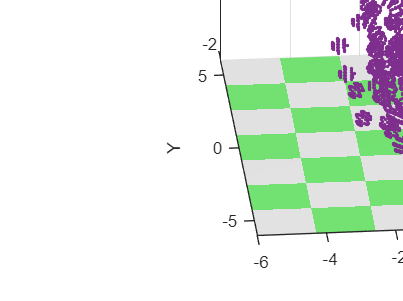

for i=1:it
    for j=1:it
        for k = 1:it
            for a = 1:it
                for b = 1:it
                    for c = 1:it
                        TCP = Robot.fkine([q(i,1),q(j,2), ...
                        q(k,3),q(a,4),q(b,5),q(c,6)]);
                        X(con) = TCP(1,4);
                        Y(con) = TCP(2,4);
                        Z(con) = TCP(3,4);
                        con = con + 1;
                    end
                end
            end
        end
    end
end
hold on
plot3(X(:),Y(:),Z(:),'.')

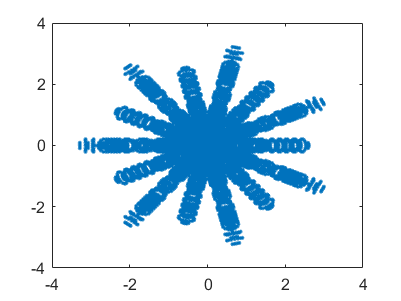


figure(2)
plot(X(:),Y(:),'.')

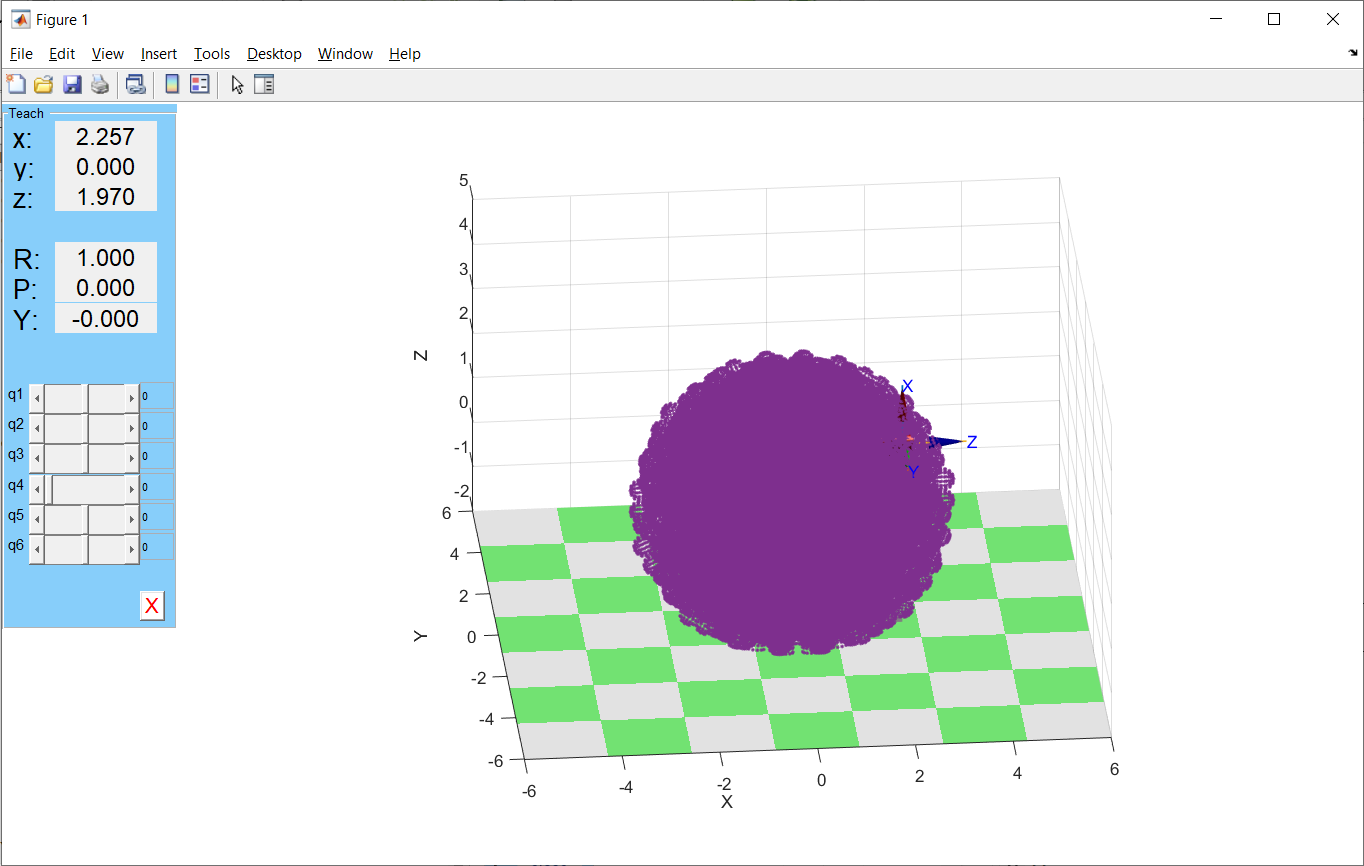

La figura de arriba se hizo con it = 15 en 3D y la de abajo con it = 8 en 2D (X,Y)